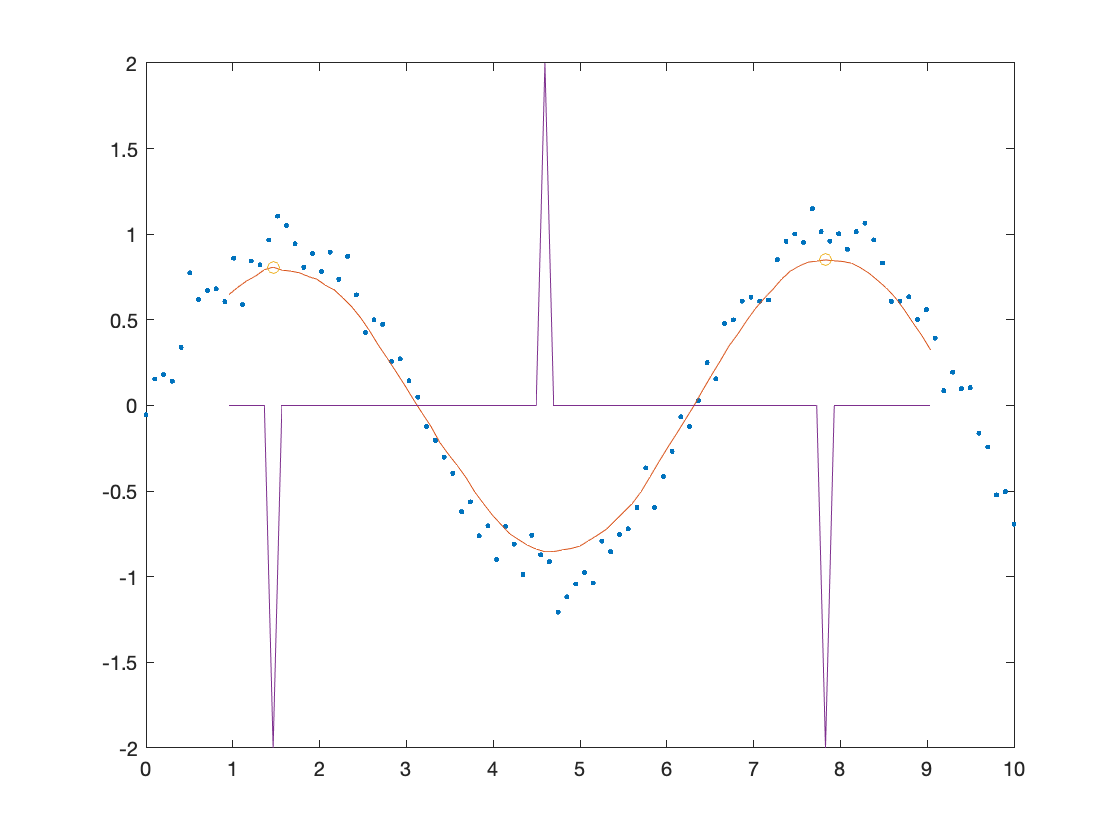

clc; clear; close all;

x = linspace(0, 10);
y = sin(x) + (randn(size(x)) * 0.1);

mask = x < 5;
mask = (x == x);
x1 = x(mask);
y1 = y(mask);

w = ones([1, 20]);
w = w/sum(w);

x2 = conv(x1, w, 'valid');
y2 = conv(y1, w, 'valid');

% Generate difference between each value
ddy = [0, diff(sign(diff(y2))), 0];
ind = (ddy == -2);

indThreshold = (y2 < 0);
indFind = find(indThreshold);

width1 = sum(indThreshold) * mean(diff(x2(y2<0)));
width2 = x2(indFind(end)) - x2(indFind(1));

plot(x, y, '.', x2, y2, '-', x2(ind), y2(ind), 'o', x2, ddy, '-')

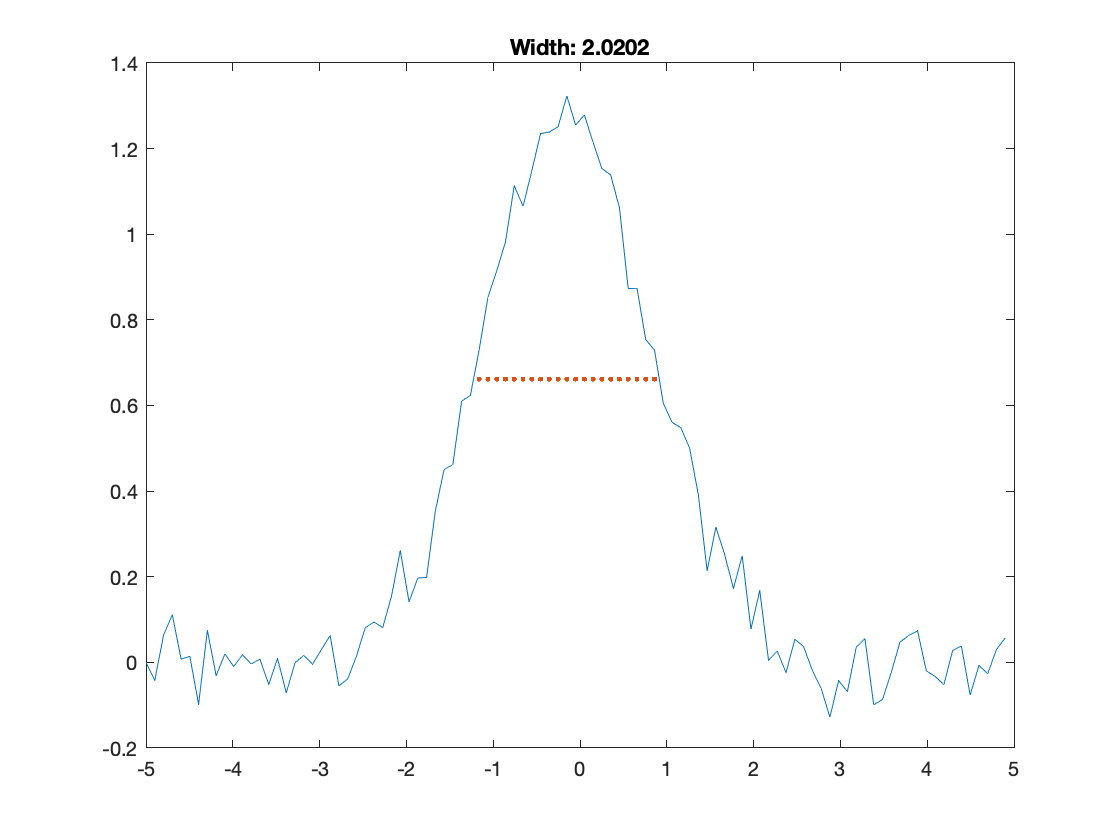

clc; clear; close all;

x = linspace(-1,1) * 5;
x = x(1:(end-1));
y = exp(-((x-randn(1))/(1+rand(1))).^2)*(1+rand(1))+randn(size(x))*0.05;

[yMax, indMax] = max(y);

yt = yMax/2; % calculate threshold (half max)
ind = find(y > yt); % find when y exceeds threshold
w = x(ind(end)) - x(ind(1)); % calculate the width

plot(x,y,'-',x(ind), yt * ones(size(x(ind))),'.') % overlay for confirmation
title("Width: " + w);